# Task1-Point Processing and Image Histograms

% MELTEM BAYKAL-170315068
clearvars;
close all;
clc;

## A0 Image:

I = imread('task1_images/A0.tif');
if(size(I,3) == 3)
    I = rgb2gray(I);
end

* I= I-128*

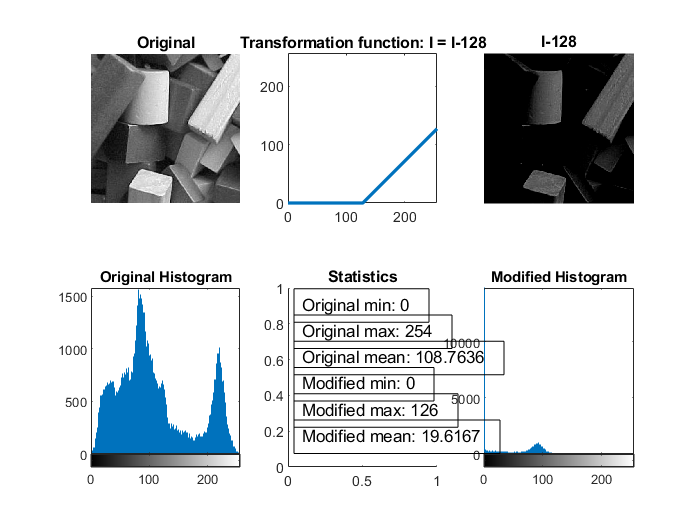

x = 0:255;
y = x-128;
ind = find(y<0); 
y(ind) = 0; 

I1 =imsubtract(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth',2), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;
subplot(2,3,3), imshow(I1),title('I-128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics'),
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I1));
s5 = max(max(I1));
s6 = mean(mean(I1));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I1), title('Modified Histogram');

*I = I+128*

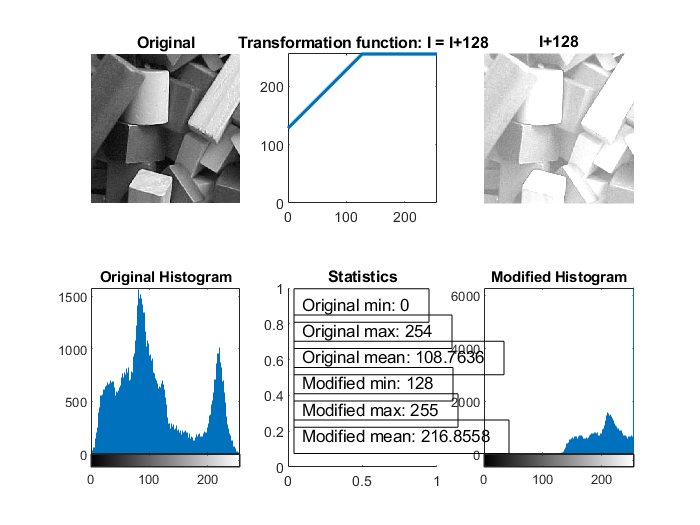

x = 0:255;
y = x+128;
ind = find(y>255);
y(ind)=255;
I2 =imadd(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I+128'), axis square;
subplot(2,3,3), imshow(I2),title('I+128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics'),
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I2));
s5 = max(max(I2));
s6 = mean(mean(I2));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I2), title('Modified Histogram');

*I = I*2*

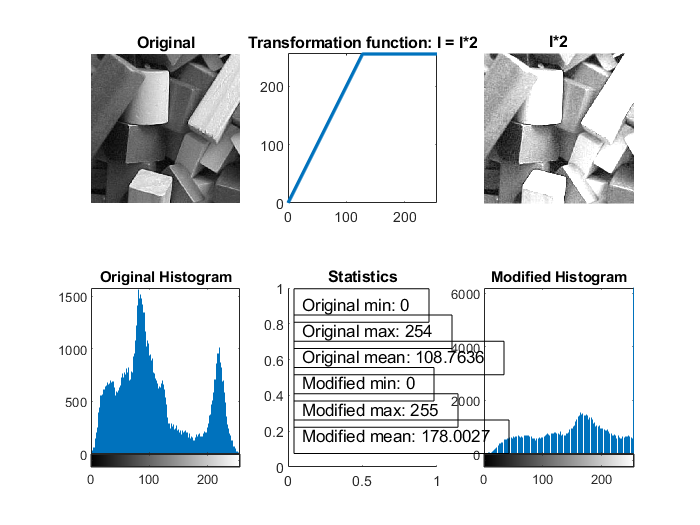

x = 0:255;
y = x*2;
ind = find(y>255); 
y(ind) = 255; 
I3 =immultiply(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;
subplot(2,3,3), imshow(I3),title('I*2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I3));
s5 = max(max(I3));
s6 = mean(mean(I3));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I3), title('Modified Histogram');

*I = I/2*

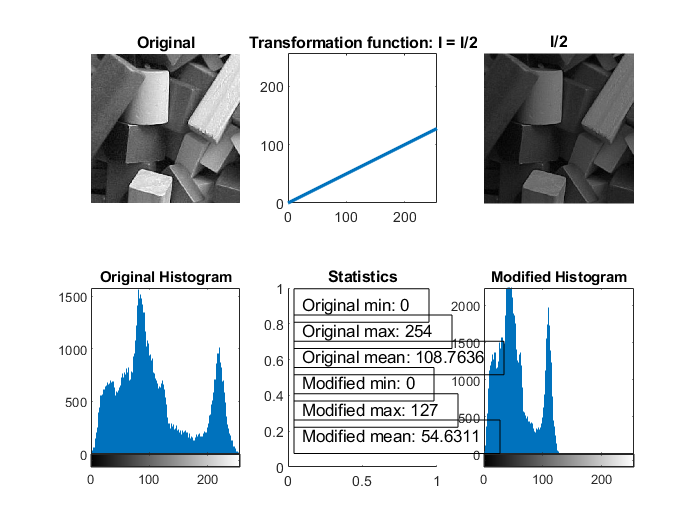

x = 0:255;
y = x/2;

I4 =imdivide(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;
subplot(2,3,3), imshow(I4),title('I/2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I4));
s5 = max(max(I4));
s6 = mean(mean(I4));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I4), title('Modified Histogram');

*Negative images*

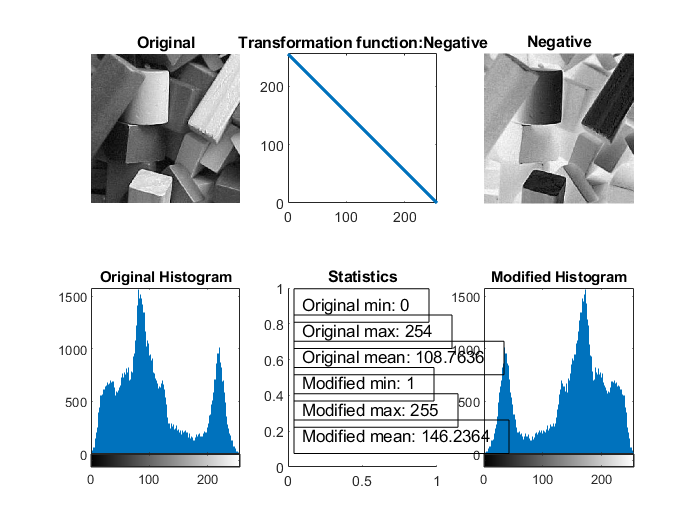

x = 0:255;
y = 255-x;

I5 =imcomplement(I);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function:Negative'), axis square;
subplot(2,3,3), imshow(I5),title('Negative'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I5));
s5 = max(max(I5));
s6 = mean(mean(I5));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I5), title('Modified Histogram');

## A1 Image:

I = imread('task1_images/A1.tif');
if(size(I,3) == 3)
    I = rgb2gray(I);
end

* I= I-128*

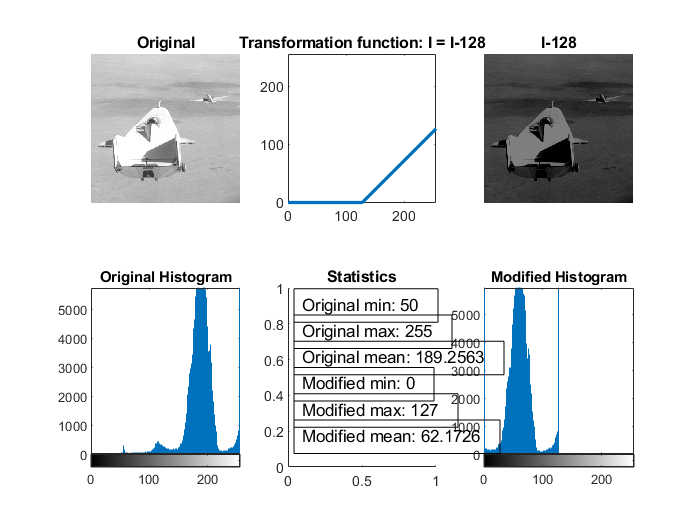

x = 0:255;
y = x-128;
ind = find(y<0); 
y(ind) = 0; 

I1 =imsubtract(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth',2), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;
subplot(2,3,3), imshow(I1),title('I-128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I1));
s5 = max(max(I1));
s6 = mean(mean(I1));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I1), title('Modified Histogram');

*I = I+128*

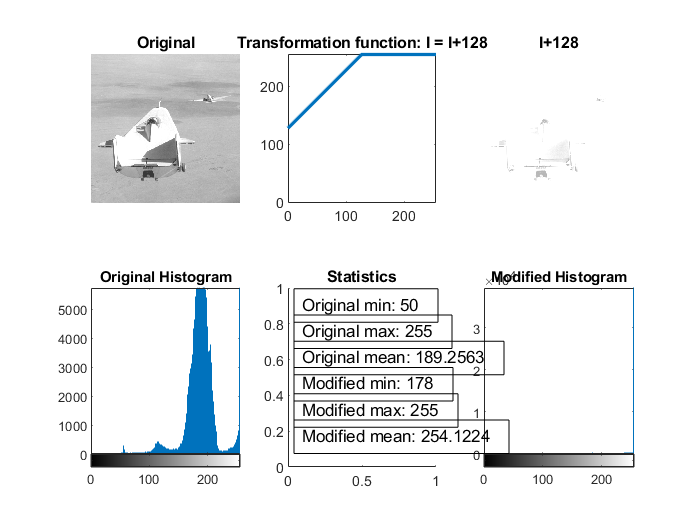

x = 0:255;
y = x+128;
ind = find(y>255);
y(ind)=255;
I2 =imadd(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I+128'), axis square;
subplot(2,3,3), imshow(I2),title('I+128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I2));
s5 = max(max(I2));
s6 = mean(mean(I2));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I2), title('Modified Histogram');

*I = I*2*

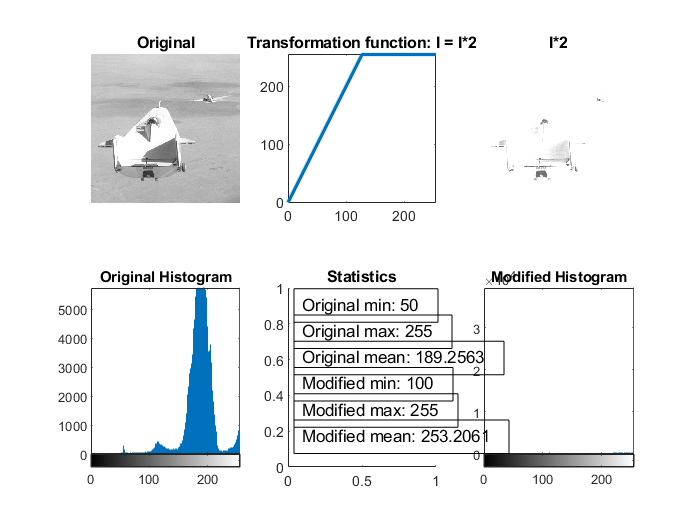

x = 0:255;
y = x*2;
ind = find(y>255); 
y(ind) = 255; 
I3 =immultiply(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;
subplot(2,3,3), imshow(I3),title('I*2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I3));
s5 = max(max(I3));
s6 = mean(mean(I3));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I3), title('Modified Histogram');

*I = I/2*

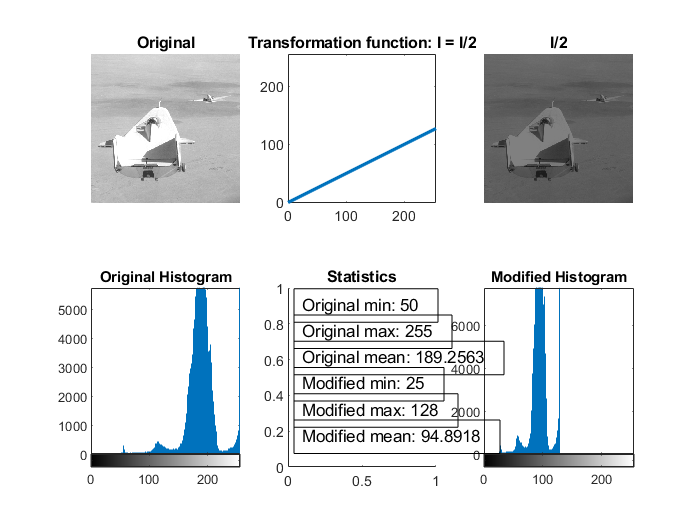

x = 0:255;
y = x/2;

I4 =imdivide(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;
subplot(2,3,3), imshow(I4),title('I/2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I4));
s5 = max(max(I4));
s6 = mean(mean(I4));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I4), title('Modified Histogram');

*Negative images*

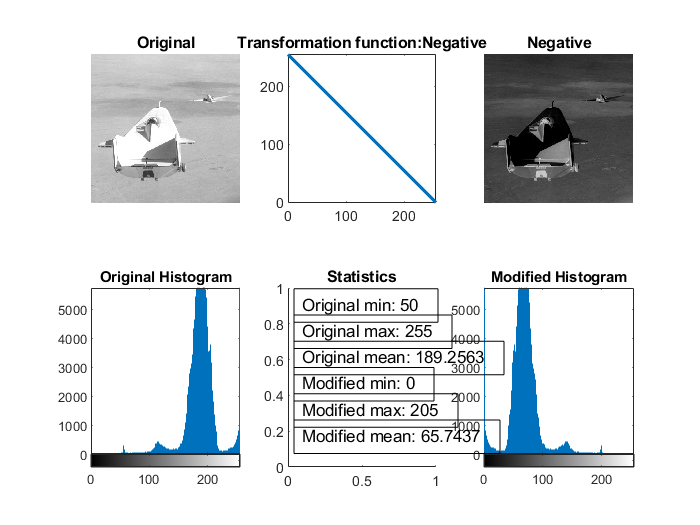

x = 0:255;
y = 255-x;

I5 =imcomplement(I);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function:Negative'), axis square;
subplot(2,3,3), imshow(I5),title('Negative'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I5));
s5 = max(max(I5));
s6 = mean(mean(I5));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I5), title('Modified Histogram');

## A2 Image:

I = imread('task1_images/A2.tif');
if(size(I,3) == 3)
    I = rgb2gray(I);
end

* I= I-128*

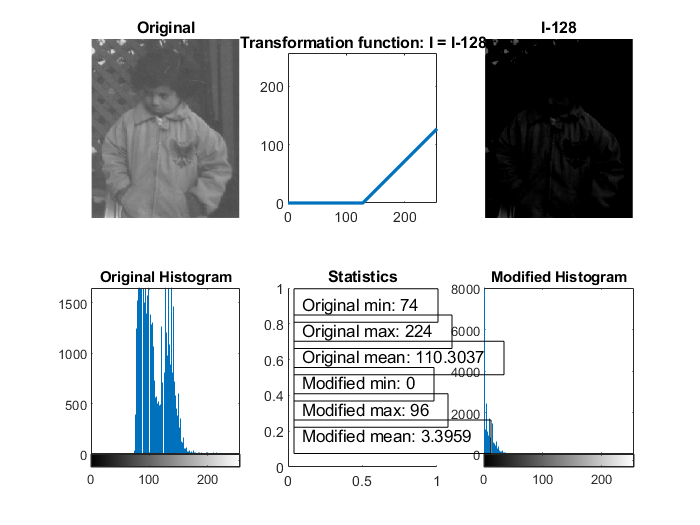

x = 0:255;
y = x-128;
ind = find(y<0); 
y(ind) = 0; 

I1 =imsubtract(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth',2), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;
subplot(2,3,3), imshow(I1),title('I-128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I1));
s5 = max(max(I1));
s6 = mean(mean(I1));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I1), title('Modified Histogram');

*I = I+128*

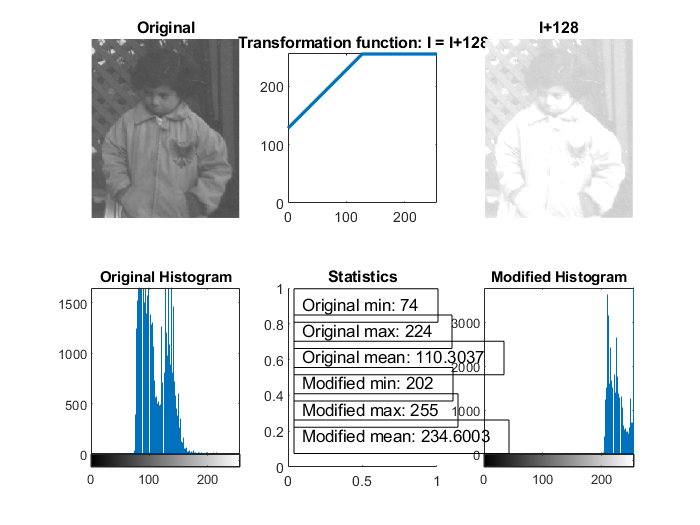

x = 0:255;
y = x+128;
ind = find(y>255);
y(ind)=255;
I2 =imadd(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I+128'), axis square;
subplot(2,3,3), imshow(I2),title('I+128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I2));
s5 = max(max(I2));
s6 = mean(mean(I2));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I2), title('Modified Histogram');

*I = I*2*

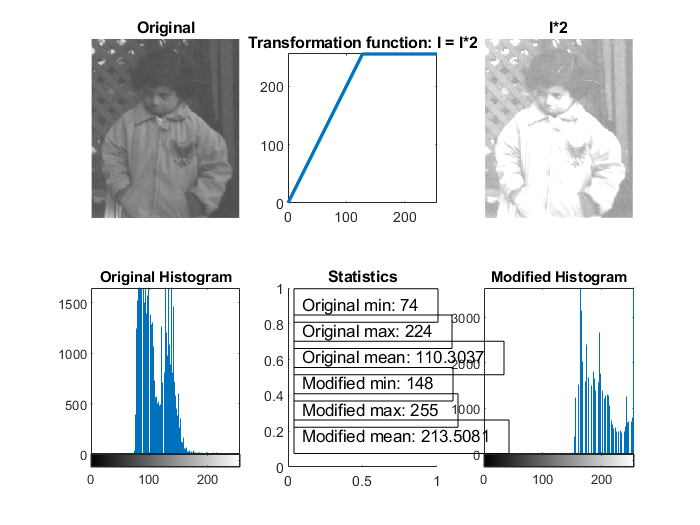

x = 0:255;
y = x*2;
ind = find(y>255); 
y(ind) = 255; 
I3 =immultiply(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;
subplot(2,3,3), imshow(I3),title('I*2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I3));
s5 = max(max(I3));
s6 = mean(mean(I3));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I3), title('Modified Histogram');

*I = I/2*

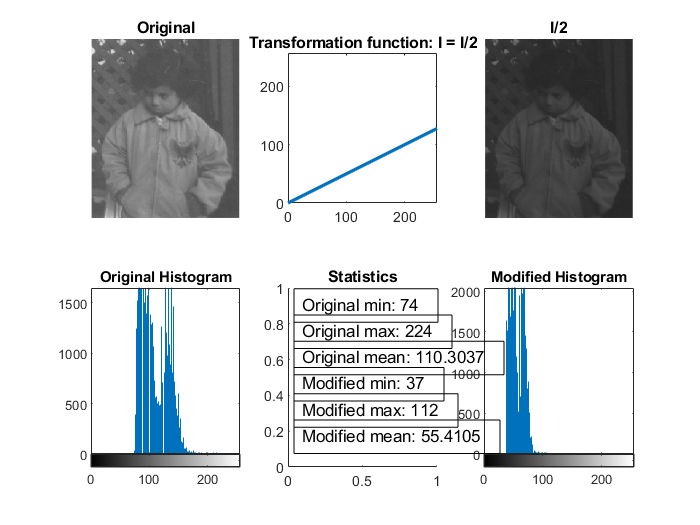

x = 0:255;
y = x/2;

I4 =imdivide(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;
subplot(2,3,3), imshow(I4),title('I/2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I4));
s5 = max(max(I4));
s6 = mean(mean(I4));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I4), title('Modified Histogram');

*Negative images*

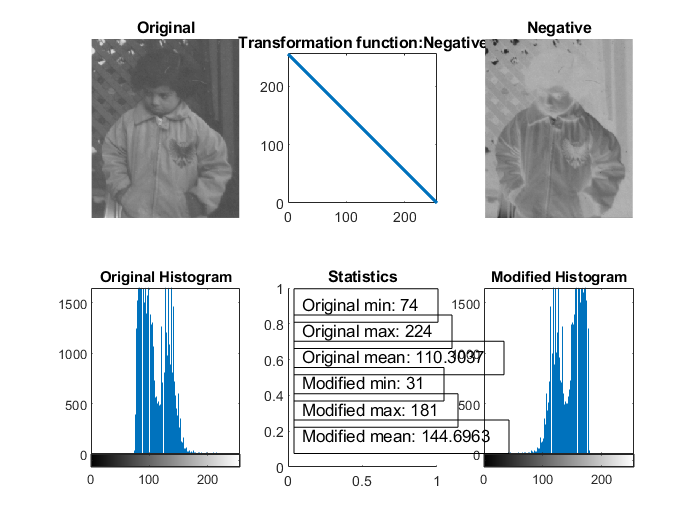

x = 0:255;
y = 255-x;

I5 =imcomplement(I);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function:Negative'), axis square;
subplot(2,3,3), imshow(I5),title('Negative'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I5));
s5 = max(max(I5));
s6 = mean(mean(I5));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I5), title('Modified Histogram');

## A3 Image:

I = imread('task1_images/A3.tif');
if(size(I,3) == 3)
    I = rgb2gray(I);
end

* I= I-128*

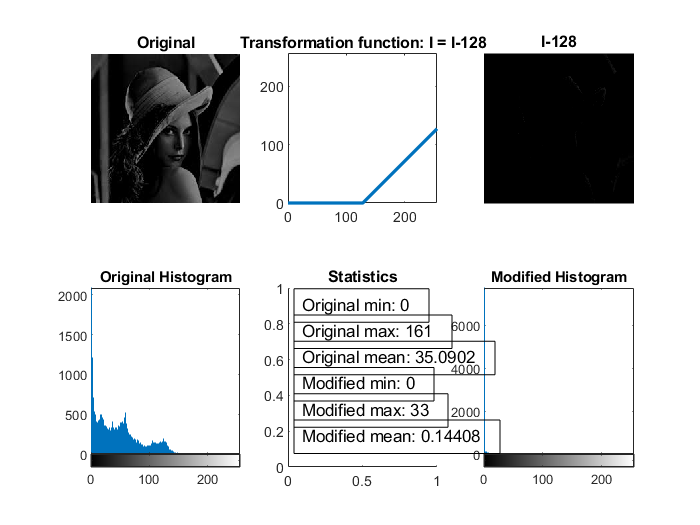

x = 0:255;
y = x-128;
ind = find(y<0); 
y(ind) = 0; 

I1 =imsubtract(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth',2), axis([0 255 0 255]), title('Transformation function: I = I-128'), axis square;
subplot(2,3,3), imshow(I1),title('I-128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I1));
s5 = max(max(I1));
s6 = mean(mean(I1));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I1), title('Modified Histogram');

*I = I+128*

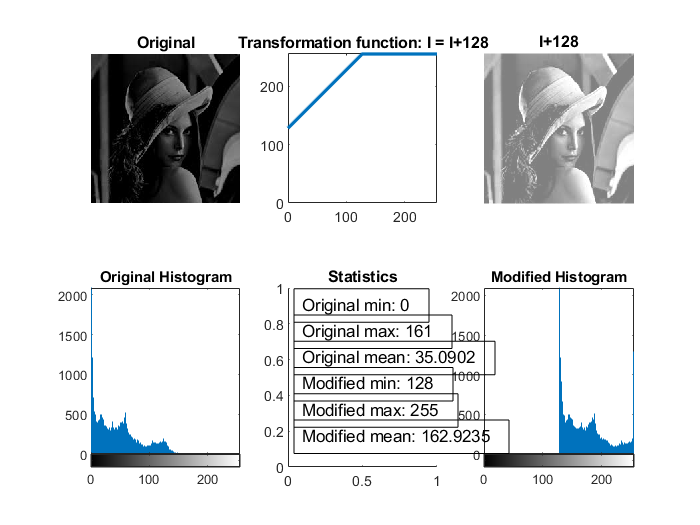

x = 0:255;
y = x+128;
ind = find(y>255);
y(ind)=255;
I2 =imadd(I,128);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I+128'), axis square;
subplot(2,3,3), imshow(I2),title('I+128'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I2));
s5 = max(max(I2));
s6 = mean(mean(I2));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I2), title('Modified Histogram');

*I = I*2*

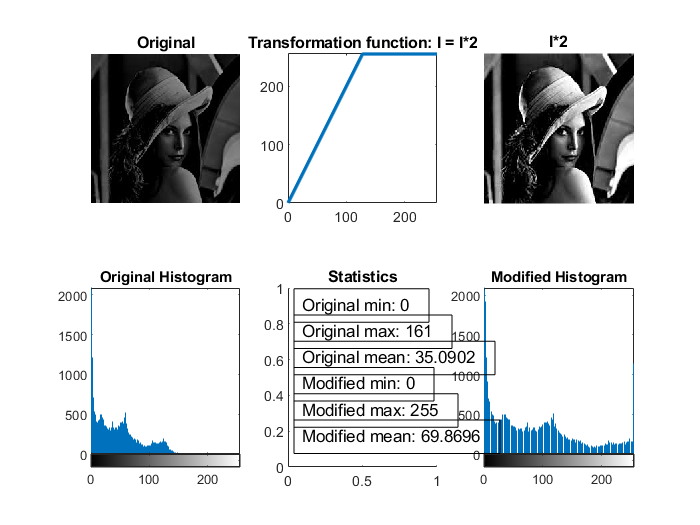

x = 0:255;
y = x*2;
ind = find(y>255); 
y(ind) = 255; 
I3 =immultiply(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I*2'), axis square;
subplot(2,3,3), imshow(I3),title('I*2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I3));
s5 = max(max(I3));
s6 = mean(mean(I3));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I3), title('Modified Histogram');

*I = I/2*

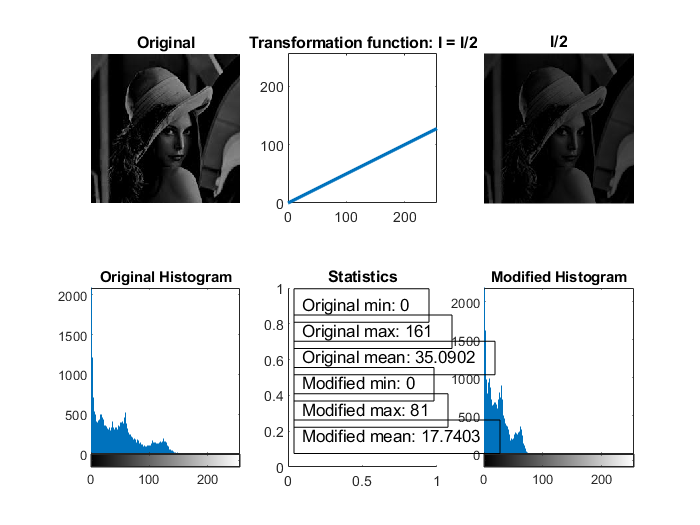

x = 0:255;
y = x/2;

I4 =imdivide(I,2);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function: I = I/2'), axis square;
subplot(2,3,3), imshow(I4),title('I/2'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I4));
s5 = max(max(I4));
s6 = mean(mean(I4));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I4), title('Modified Histogram');

*Negative images*

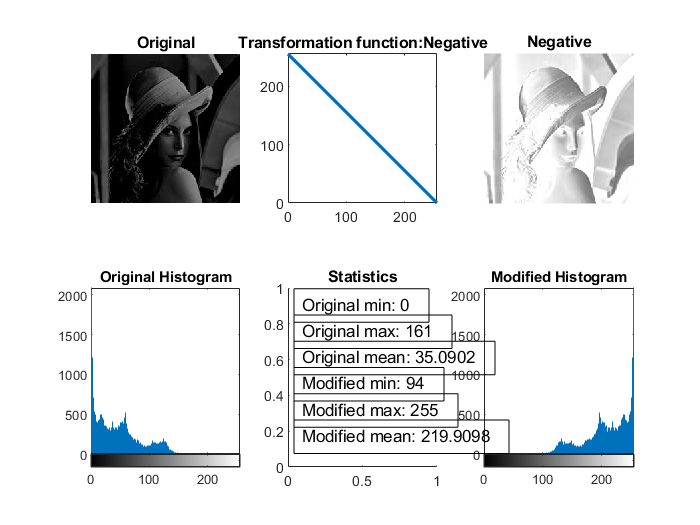

x = 0:255;
y = 255-x;

I5 =imcomplement(I);

figure,subplot(2,3,1), imshow(I), title('Original'); 
subplot(2,3,2),plot(x,y,'LineWidth', 2), axis([0 255 0 255]), title('Transformation function:Negative'), axis square;
subplot(2,3,3), imshow(I5),title('Negative'); 
subplot(2,3,4), imhist(I), title('Original Histogram');
subplot(2,3,5), title('Statistics');
s1 = min(min(I));
s2 = max(max(I));
s3 = mean(mean(I));
s4 = min(min(I5));
s5 = max(max(I5));
s6 = mean(mean(I5));
annotation('textbox',[0.42, 0.35, 0.1, 0.1],'String',"Original min: " + s1);
annotation('textbox',[0.42, 0.30, 0.1, 0.1],'String',"Original max: " + s2);
annotation('textbox',[0.42, 0.25, 0.1, 0.1],'String',"Original mean: " + s3);
annotation('textbox',[0.42, 0.20, 0.1, 0.1],'String',"Modified min: " + s4);
annotation('textbox',[0.42, 0.15, 0.1, 0.1],'String',"Modified max: " + s5);
annotation('textbox',[0.42, 0.10, 0.1, 0.1],'String',"Modified mean: " + s6);
subplot(2,3,6), imhist(I5), title('Modified Histogram');